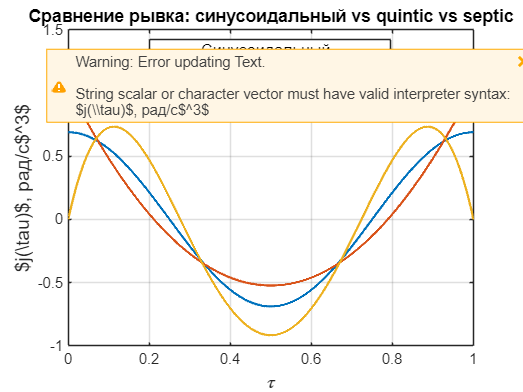

clear all; clc;

% Параметры манёвра
theta_total = deg2rad(1);   % Δθ, например 1 град (любой угол)
T = 1.0;                    % длительность манёвра, с

% Нормированное время
N = 2000;
tau = linspace(0,1,N);

% --- РЫВОК ДЛЯ РАЗНЫХ ПРОФИЛЕЙ ---

% 1) Синусоидальный (циклоидальный): j_sin(τ) = (4π^2 Δθ / T^3) * cos(2π τ)
j_sin = (4*pi^2*theta_total/T^3) .* cos(2*pi*tau);

% 2) Quintic (5-й порядок):
% θ(τ) = Δθ * (10τ^3 - 15τ^4 + 6τ^5)
% j_quintic(τ) = (Δθ/T^3) * 60*(1 - 6τ + 6τ^2)
j_quintic = (theta_total/T^3) .* (60*(1 - 6*tau + 6*tau.^2));

% 3) Septic (7-й порядок, C^3-гладкость, j(0)=j(1)=0):
% θ(τ) = Δθ * (35τ^4 - 84τ^5 + 70τ^6 - 20τ^7)
% j_septic(τ) = (Δθ/T^3) * (840τ - 5040τ^2 + 8400τ^3 - 4200τ^4)
j_septic = (theta_total/T^3) .* (840*tau - 5040*tau.^2 + 8400*tau.^3 - 4200*tau.^4);

% --- ГРАФИКИ ---
figure('Color','w');
plot(tau, j_sin,    'LineWidth',1.6); hold on;
plot(tau, j_quintic,'LineWidth',1.6);
plot(tau, j_septic, 'LineWidth',1.6);
grid on; xlim([0 1]);
xlabel('$\tau$','Interpreter','latex','FontSize',13);
ylabel('$j(\tau)$, рад/с$^3$','Interpreter','latex','FontSize',13);
title('Сравнение рывка: синусоидальный vs quintic vs septic','FontSize',12);
legend({'Синусоидальный','Quintic (5-й)','Septic (7-й, $j(0)=j(1)=0$)'}, ...
       'Interpreter','latex','Location','best','FontSize',11);

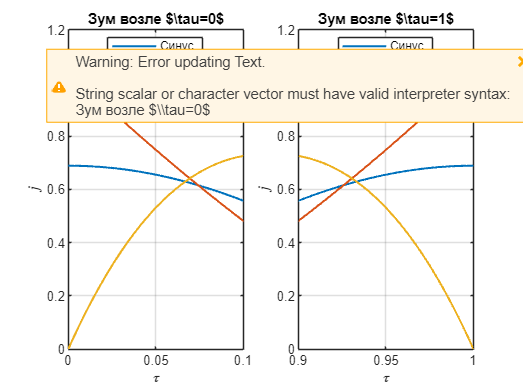


% Доп. зум у границ, чтобы увидеть поведение рывка на концах
figure('Color','w');
subplot(1,2,1);
plot(tau, j_sin, 'LineWidth',1.4); hold on;
plot(tau, j_quintic, 'LineWidth',1.4);
plot(tau, j_septic, 'LineWidth',1.4);
grid on; xlim([0 0.1]);
xlabel('$\tau$','Interpreter','latex'); ylabel('$j$', 'Interpreter','latex');
title('Зум возле $\tau=0$','Interpreter','latex');
legend({'Синус','Quintic','Septic'},'Interpreter','latex','Location','best');

subplot(1,2,2);
plot(tau, j_sin, 'LineWidth',1.4); hold on;
plot(tau, j_quintic, 'LineWidth',1.4);
plot(tau, j_septic, 'LineWidth',1.4);
grid on; xlim([0.9 1]);
xlabel('$\tau$','Interpreter','latex'); ylabel('$j$', 'Interpreter','latex');
title('Зум возле $\tau=1$','Interpreter','latex');
legend({'Синус','Quintic','Septic'},'Interpreter','latex','Location','best');